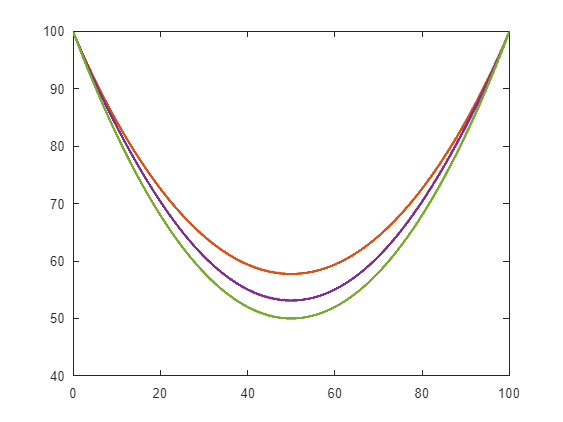

order = 7;
targets = [0,100; 50,0; 100,100];
CP = points(targets, order);
knot = knotvect(CP, order, pmin, pmax, pstep);
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
plot(PosMAT(:,1),PosMAT(:,2), 'Color', "#D95319", 'LineWidth', 2)
hold on
xlim([0, 100]);
%scatter(CPx, CPy, 60, 'red', 'X')
order = 6;
CP = points(targets, order);
knot = knotvect(CP, order, pmin, pmax, pstep);
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
%plot(PosMAT(:,1),PosMAT(:,2), 'Color', "red", 'LineWidth', 2)
order = 5;
CP = points(targets, order);
knot = knotvect(CP, order, pmin, pmax, pstep);
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
plot(PosMAT(:,1),PosMAT(:,2), 'Color', "#7E2F8E", 'LineWidth', 2)
order = 4;
CP = points(targets, order);
knot = knotvect(CP, order, pmin, pmax, pstep);
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
%plot(PosMAT(:,1),PosMAT(:,2), 'Color',"blue", 'LineWidth', 2)
order = 3;
CP = points(targets, order);
knot = knotvect(CP, order, pmin, pmax, pstep);
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
plot(PosMAT(:,1),PosMAT(:,2), 'Color',"#77AC30", 'LineWidth', 2)
hold off

function pMAT = pMAT(p,knot,k)
    N = length(knot);
    pMAT = [];
    for i = 1:1:N-k
        pconst1 = (p-knot(1,i))/(knot(1,i+k-1)-knot(1, i));
        pconst2 = (knot(1,i+k)-p)/(knot(1,i+k)-knot(1,i+1));
        Head = zeros(i-1,1);
        Foot = zeros(N-k-i,1);
        pvect = [Head; pconst1; pconst2; Foot];
        pMAT = [pMAT, pvect];
    end
end
function CP = points(targets, order)
    P = height(targets);
    rep = order - 2;
    CP = [];
    hold = [targets(1,1), targets(1,2)];
    for n = 1:1:rep
        CP = [CP; hold];
    end
    for i = 2:1:P-1
        hold = [targets(i,1), targets(i,2)];
        CP = [CP; hold];
    end
    hold = [targets(P,1), targets(P,2)];
    for k = 1:1:rep
        CP = [CP; hold];
    end
end
function Knot = knotvect(CP, order, pmin, pmax, pstep)
    sz = size(CP);
    P = sz(1,1);
    K = P + order;
    Knot = pmin;
    for i = 1:1:order-1
        Knot = [Knot, pmin+i*pstep];
    end
    for i = 1:1:K-2*order
        Knot = [Knot, i*pmax/(K-2*order+1)];
    end
    for i = 1:1:order
        Knot = [Knot, pmax-(order-i)*pstep];
    end
end
function NK1MAT = NK1MAT(p, knot)
    N = length(knot);
    NK1MAT = [];
    for i = 1:1:N-1
        lowkn = knot(i);
        highkn = knot(i+1);
        if lowkn<=p && p<highkn
            NK1MAT = [NK1MAT, 1];
        else
            NK1MAT = [NK1MAT, 0];
        end
    end
end

function BSplineMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order)
    BSplineMAT = [];
    for p = pmin:pstep:pmax
        if p >= validpmin
            if p<=validpmax
                k = 2;
                NK2MAT = NK1MAT(p, knot)*pMAT(p, knot, k);
                k = 3;
                NK3MAT = NK2MAT*pMAT(p, knot, k);
                k = 4;
                if order < k
                    Pos = NK3MAT*CP;
                else
                    NK4MAT = NK3MAT*pMAT(p, knot, k);
                    k = 5;
                    if order < k
                        Pos = NK4MAT*CP;
                    else
                        NK5MAT = NK4MAT*pMAT(p, knot, k);
                        k = 6;
                        if order < k
                            Pos = NK5MAT*CP;
                        else
                            NK6MAT = NK5MAT*pMAT(p, knot, k);
                            k = 7;
                            if order < k
                                Pos = NK6MAT*CP;
                            else
                                NK7MAT = NK6MAT*pMAT(p, knot, k);
                                Pos = NK7MAT*CP;
                            end
                        end
                    end
                end
                BSplineMAT = [BSplineMAT; Pos];
            end
        end
    end
end

function DP = DCP(CP, knot, k)
    n = length(CP);
    DP = [];
    for i = 1:1:n-1
        I = i+1;
        P1 = [CP(i,1),CP(i,2)];
        P2 = [CP(i+1,1),CP(i+1,2)];
        DPnew = (P2-P1)*k/(knot(I+k)-knot(I));
        DP = [DP; DPnew];
    end
end
function DKnot = Dkn(knot)
    N = length(knot);
    DKnot = [];
    for i = 1:1:N-2
        DKnew = knot(i+1);
        DKnot = [DKnot, DKnew];
    end
end
function MagMAT = absBS(Pos)
    N = length(Pos.');
    MagMAT = [];
    for i = 1:1:N
        X = Pos(i,1);
        Y = Pos(i,2);
        abs = sqrt(X^2+Y^2);
        MagMAT = [MagMAT; i, abs];
    end
end